|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       layers |      neurons |    learnRate |    optimizer |   activation |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |
|==================================================================================================================================================|
|    1 | Best   |  1.9819e+05 |      8.5471 |  1.9819e+05 |  1.9819e+05 |            4 |           14 |    0.0018549 |         sgdm |         tanh |
|    2 | Accept |  2.6658e+05 |      1.5973 |  1.9819e+05 |  2.1029e+05 |            3 |           29 |     0.087527 |      rmsprop |         relu |
|    3 | Accept |  2.0284e+05 |      3.5551 |  1.9819e+05 |  1.9823e+05 |            8 |           44 |   

|    5 | Error  |         NaN |      0.6899 |  1.9819e+05 |  1.9861e+05 |            3 |           44 |     0.008271 |         sgdm |         relu |


|    6 | Error  |         NaN |      0.7116 |  1.9819e+05 |  1.9861e+05 |            4 |           39 |     0.008249 |         sgdm |         relu |
|    7 | Accept |  8.2523e+05 |      2.1225 |  1.9819e+05 |  3.3256e+05 |            4 |           43 |    0.0082242 |      rmsprop |         tanh |
|    8 | Accept |  1.9827e+05 |      2.0685 |  1.9819e+05 |  1.9824e+05 |            4 |           14 |     0.001855 |         sgdm |         tanh |
|    9 | Best   |  1.9802e+05 |      3.6585 |  1.9802e+05 |  1.9817e+05 |            9 |           14 |   0.00091395 |         sgdm |         tanh |
|   10 | Accept |  8.7289e+05 |      3.9239 |  1.9802e+05 |  1.9817e+05 |           10 |           14 |   0.00010927 |      rmsprop |         tanh |
|   11 | Accept |  2.0529e+05 |      2.1078 |  1.9802e+05 |  1.9817e+05 |            8 |           33 |     0.049098 |         adam |         relu |
|   12 | Accept |  6.7228e+05 |      3.7389 |  1.9802e+05 |  1.9817e+05 |            9 |           50 |   

|   32 | Error  |         NaN |      2.8049 |  1.9179e+05 |  1.9164e+05 |            7 |           50 |     0.098686 |         sgdm |         tanh |
|   33 | Accept |  3.3345e+05 |      2.2347 |  1.9179e+05 |  1.9165e+05 |           10 |           10 |     0.099894 |      rmsprop |         relu |
|   34 | Accept |   4.467e+05 |      3.2307 |  1.9179e+05 |  1.9176e+05 |            8 |           11 |   0.00010156 |         sgdm |         tanh |
|   35 | Accept |  2.0297e+05 |      4.0341 |  1.9179e+05 |  1.9178e+05 |           10 |           31 |    0.0012477 |         sgdm |         tanh |
|   36 | Accept |  2.0258e+05 |      1.4698 |  1.9179e+05 |  1.9175e+05 |            2 |           50 |   0.00036761 |         sgdm |         tanh |
|   37 | Accept |  2.0602e+05 |      1.4319 |  1.9179e+05 |  1.9175e+05 |            2 |           50 |     0.018026 |         sgdm |         tanh |
|   38 | Accept |  3.2382e+23 |      4.0506 |  1.9179e+05 | -9.1221e+17 |           10 |           39 |   

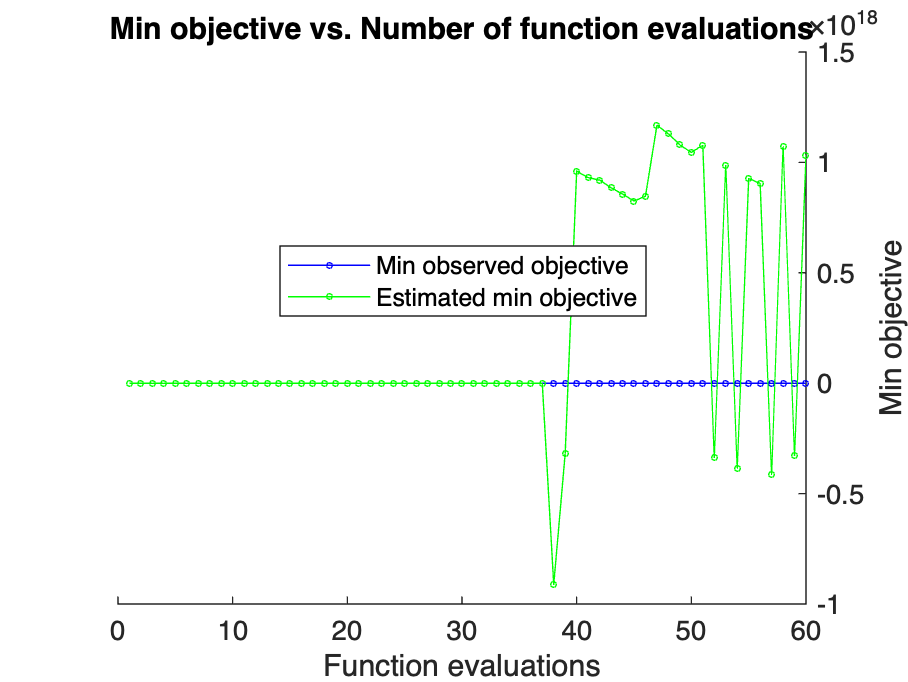

% Load the data
data = readtable('NewDataSetv2.xlsx');

% Define the features and target variable
X = data{:, {'Age', 'Yrs', 'UPDRS'}};
Y = data.LED;

% Standardize the features
X = zscore(X);

% Set up the Bayesian optimization for MLP
rng default

% Define the optimizable variables
layers = optimizableVariable('layers', [1, 10], 'Type', 'integer');
neurons = optimizableVariable('neurons', [10, 50], 'Type', 'integer');
learnRate = optimizableVariable('learnRate', [1e-4, 1e-1], 'Transform', 'log');
optimizer = optimizableVariable('optimizer', {'sgdm', 'rmsprop', 'adam'}, 'Type', 'categorical'); 
activation = optimizableVariable('activation', {'relu', 'tanh', 'sigmoid'}, 'Type', 'categorical');

% Cross-validation partition
c = cvpartition(size(data, 1), 'Kfold', 5);

% Define the objective function for Bayesian optimization
fun = @(x)kfoldLossForMLP(X, Y, c, x.layers, x.neurons, x.learnRate, char(x.optimizer), char(x.activation));

results = bayesopt(fun, [layers, neurons, learnRate, optimizer, activation], ...
    'Verbose', 1, ...
    'AcquisitionFunctionName', 'expected-improvement-plus', ...
    'MaxObjectiveEvaluations', 60);  % Set the number of evaluations


% Display the best hyperparameters
bestParams = bestPoint(results);
disp('Best hyperparameters:');

Best hyperparameters:


disp(bestParams);

    layers    neurons    learnRate    optimizer    activation
    ______    _______    _________    _________    __________

      4         14       0.0018549      sgdm          tanh   




% Display the results table
disp('Optimization results:');

Optimization results:


disp(results.XTrace);

    layers    neurons    learnRate     optimizer    activation
    ______    _______    __________    _________    __________

       4        14        0.0018549     sgdm         tanh     
       3        29         0.087527     rmsprop      relu     
       8        44        0.0002135     sgdm         sigmoid  
       9        10        0.0014432     adam         sigmoid  
       3        44         0.008271     sgdm         relu     
       4        39         0.008249     sgdm         relu     
       4        43        0.0082242     rmsprop      tanh     
       4        14         0.001855     sgdm         tanh     
       9        14       0.00091395     sgdm         tanh     
      10        14       0.00010927     rmsprop      tanh     
       8        33         0.049098     adam         relu     
       9  


% Function to compute cross-validated loss for MLP
function loss = kfoldLossForMLP(X, Y, c, numLayers, numNeurons, learnRate, optimizer, activation)
    losses = zeros(c.NumTestSets, 1);
    for i = 1:c.NumTestSets
        trainIdx = training(c, i);
        testIdx = test(c, i);
        layerArray = [
            featureInputLayer(size(X, 2), 'Normalization', 'zscore')
        ];
        for l = 1:numLayers
            layerArray = [
                layerArray
                fullyConnectedLayer(numNeurons)
                activationLayer(activation)
            ];
        end
        layerArray = [
            layerArray
            fullyConnectedLayer(1)
            regressionLayer
        ];

        % Set up training options
        options = trainingOptions(optimizer, ...
            'InitialLearnRate', learnRate, ...
            'MaxEpochs', 50, ...
            'MiniBatchSize', 64, ...
            'Shuffle', 'every-epoch', ...
            'Plots', 'none', ...
            'Verbose', false);

        % Add try-catch for errors
        try
            net = trainNetwork(X(trainIdx, :), Y(trainIdx), layerArray, options);

     
            predictions = predict(net, X(testIdx, :));
            testLoss = mean((predictions - Y(testIdx)).^2);

            losses(i) = testLoss;
        catch ME
            warning('Training failed for fold %d: %s', i, ME.message);
            losses(i) = Inf; 
        end
    end
    loss = mean(losses);
end

% Helper function to create activation layers
function layer = activationLayer(type)
    switch type
        case 'relu'
            layer = reluLayer;
        case 'tanh'
            layer = tanhLayer;
        case 'sigmoid'
            layer = sigmoidLayer;
        otherwise
            error('Unsupported activation type');
    end
end


